# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.19 求助大佬，如何自动识别并校正曲线不连续的部分?

类似下图这样的曲线，中间部位会出现不连续点，但是位置不固定，如何用MATLAB实现自动识别，并将该段校正成红色虚线所示，让曲线连续。

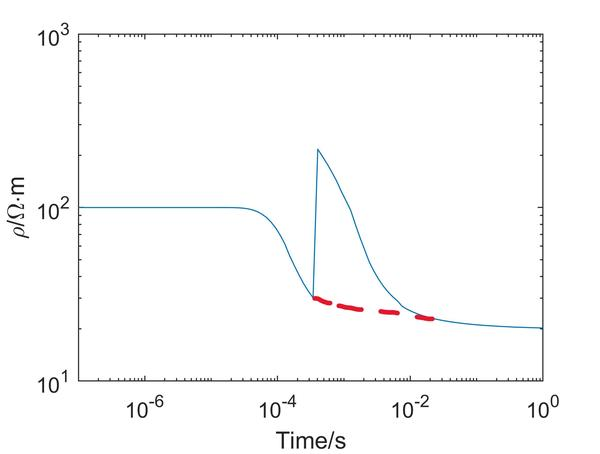

原问题：[https://www.zhihu.com/question/663449062](https://www.zhihu.com/question/663449062)

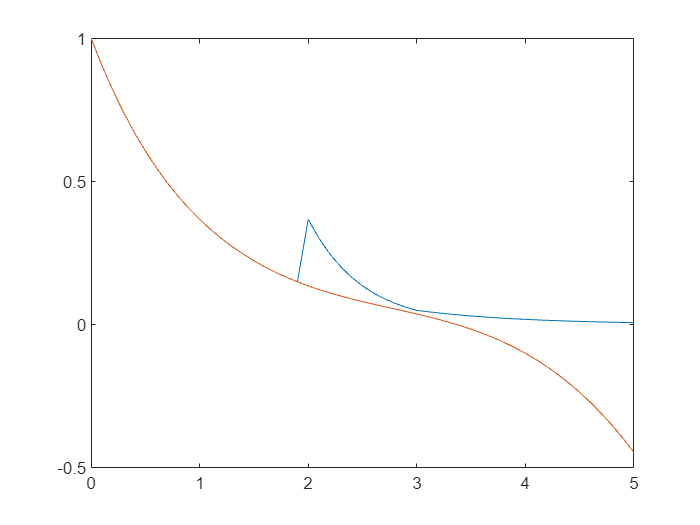

clear;clc;
x = 0:0.1:5;
y = exp(-x)';
yy = y;
yy(21:30) = y(11:2:30);
% 以上图为例，有一个突变点，计算它的一阶偏导，找最大值
% 从这个序号开始，后面的几个值是突变值，至于具体有几个，另外再讨论
% dy = abs(diff(y))';
dyy = diff(yy)';
% 用绝对值
[~, idx] = max(abs(dyy));
% 考虑前面的变化趋势，看看有没有更好的方法
% 这里用插值法
x1 = x(1:idx);
y1 = yy(1:idx);
ys = spline(x1, y1, x);
plot(x, yy, x, ys);

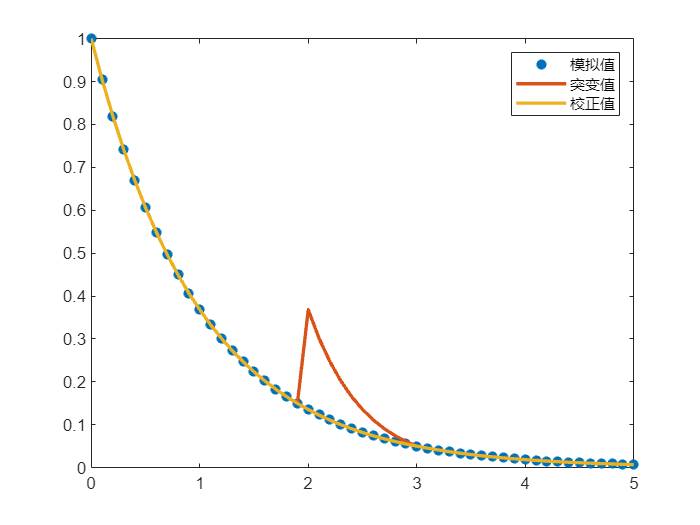

% 比较插值和突变值，找到最后一个突变值
y2 = ys(idx + 1 : end)';
y3 = yy(idx + 1 : end);
dist = abs(y2 - y3);
[~, ind] = min(dist);
% 最后的曲线段，突变段再来一次插值
x2 = x([1:idx, idx + ind :end]);
y4 = yy([1:idx, idx + ind :end]);
y5 = spline(x2, y4, x);
plot(x, y, '*', x, yy, x, y5, 'LineWidth', 2);
legend('模拟值', '突变值', '校正值');